clc;
clearvars;

**Input variables:**

% Variable                              % Explanation                             Unit
W0 = 100;                               % Mass flow                               (kg/s)
R = 287.05;                             % Gas constant                            (J/kgK)
IntakeP_loss = 0;                       % Intake pressure loss                    (%)
ExhaustP_loss = 0;                      % Exhaust pressure loss                   (kPa)
JetpipeP_loss = 0;                      % Jet pipe pressure loss                  (%)
CD = 1;                                 % Coefficient of discharge                (%)
CX = 1;                                 % Coefficient of thrust                   (%)
Mech_Eff = 0.86;                        % Mechanical efficiency                   (%)

**Input height: calculates temperature and pressure**

h = [100, 200, 300, 400, 500, 600, 700, 800, 900, 1000, 2000, 3000, 4000, 5000, 6000, 7000];

Pb = 101.325;
Tb = 288.2;
hb = 0;
Lb = 0.0065;
g = 9.80665;
Mol = 0.0289644;
R1 = 8.3144598;
P0 = Pb * ((Tb - (h - hb) * Lb)/Tb).^((g * Mol)/(R1 * Lb));

T0 = Tb - (h * Lb);

**Compressor:**

y_c = 1.4;                              % Heat capacity ratio compressor          (-)
ETA2 = 0.9;                             % Compressor isentropic efficiency        (%)
ETAP2 = 0;                              % Compressor polytopic efficiency         (%)
CP_compressor = 1.000;                  % Specific heat compressor                (kJ/kg)
P3Q2 = 8;                               % Pressure ratio compressor               (-)
CompressorP_loss = 0;                   % Compressor pressure loss                (%

**Combustor:**

CombustionP_loss = 0.05;                % Combustion pressure loss                (kPa)
ETA34 = 0.999;                          % Combustion efficiency                   (%)

**Turbine:**

y_t = 1.33;                             % Heat caapcity ratio turbine             (-)
TurbineIsent_Eff = 0.86;                % Turbine isentropic efficiency           (%)
TurbinePoly_Eff = 0;                    % Turbine polytropical eff.               (%)
CP_turbine = 1.150;                     % Specific heat turbine                   (kJ/kg)

**Pressures:**

% PAMB = 101;                             % Ambient pressure                        (kPa)

**Temperatures:**

% TAMB = 288;                             % Ambient temperature                     (K)
T3_5 = 1800;                              % Temperature after combustion            (K)

**Bleed:**

Bleed1 = 0;                             % Bleed air from compressor to outlet     (%)
Bleed2 = 0;                             % Bleed air from compressor to LPT        (%)
Bleed3 = 0;                             % Bleed air from compressor to HPT        (%)
Bleed4 = 0;                             % Bleed air to first LPT nozzle           (%)
Bleed5 = 0;                             % Bleed air to second LPT nozzle          (%)

**Fuel:**

LHV = 43*10^6;                            % Calorific value fuel                    (kJ/kg)

**Stations: **

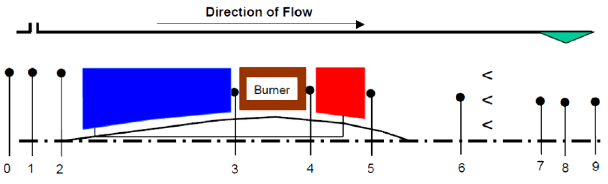

**Intake calculations:**

**Station 0: atmosperic calculations**

T0;
P0;
W0;

**Station 1: Intake**

T1 = T0;
P1 = P0;
W1 = W0;

**Station 2: Compressor inlet**

T2 = T1;
P2 = P1 * (1 - IntakeP_loss); 
W2 = W1;

**Station 2_5 :Compressor calculations: **

% ETA2 = (P3Q2^((y_c-1)/y_c)-1)/(P3Q2^((y_c-1)/(y_c*ETAP2))-1);     % Converts polytropic to isentropic                                

T2_5 = T2/ETA2 * (P3Q2^((y_c-1)/y_c)-1) + T2;
P2_5 = P3Q2 * P2;
W2_5 = W0;                                                             

Tbleed = (T2_5 + T1)/2;
PW2 = W0 * (CP_compressor) * (T2_5 - T1);                               % No Tbleed

**Station 3: Compressor outlet **

T3 = T2_5;
P3 = P2_5 * (1- CompressorP_loss);
W3 = W2_5 - (W0 * Bleed2) - (W0 * Bleed3);

**Station 3_5: Combustor calculations: **

P3_5 = P3 * (1 - CombustionP_loss);

FAR1 = 0.10118 + 2.00376E-05 * (700- T3);
FAR2 = 3.7078E-03 - 5.2368E-06 * (700 - T3) - 5.2632E-06 * T3_5;
FAR3 = 8.889E-08 * abs(T3_5 - 950);
FAR = (FAR1 - sqrt(FAR1.^2 + FAR2) - FAR3)/ETA34;

% Q = 1000 * sqrt( 2 * y_t/((y_t-1) * R) * ((1+0.2*1^2)^3.5)^(-2/y_t) * (1 - ((1+0.2*1^2)^3.5)^ ((1 - y_t)/y_t)))

Q = W2_5 * CP_turbine * (T3_5 - T3);
DT = T3_5 - T1;
DH = DT * W0 * CP_turbine;

WF = FAR * (W3 + W0 * Bleed1);                       % WF = Q/LHV (alternative formula)
W3_5 = W3 + W0 * (Bleed3) + WF;

**Station 4: Turbine inlet calculations**

W4 = W3_5 + W0 * Bleed4;
T4 = (W3_5.* CP_turbine * T3_5 + (Bleed4 * W0) * (CP_compressor)* T2_5)./(W3_5.* CP_turbine);
P4 = P3_5;

**Station 4_5: Turbine calculations:**

WC = W0 * CP_compressor * (T3 - T1);
T4_5 = T4 - (WC/(W3_5* CP_turbine));
P4_5 = P3 * (1- (1-(T4_5/T4))/TurbineIsent_Eff).^(y_t/(y_t- 1));
W4_5 = W4;

% P4_5 = P3_5* (1- (1-(T3_5/T3))/ETHA_turb).^(y_t/(y_t- 1));
% P4_5 = PAMB/(1-ExhaustP_loss);
% E415 = (1 - P415Q416^(- ((y_t-1)/y_t) * TurbineIsent_Eff))/(1 - P415Q416^(-(y_t-1)/y_t));
% T416 = E415 * T4 * (1 - P415Q416^(-((y_t-1)/y_t)));
% PW415 = W415 * CP_turbine * (T4 - T416);                
% WRTP4 = W3_5 * sqrt(T3_5)/P3_5;
% WRTP41 = W3_5 * sqrt(T41)/P3_5;

**Station 5: Turbine outlet calculations **

T5 = T4_5;
P5 = P4_5;
W5 = W4_5 + (W0 * Bleed1) + (W0 * Bleed5);

% T5 = T4_5 - (PW2/(W3_5 * CP_turbine))

**Station 6: Propelling nozzle calculations:**

T6 = T5;                                                           % P7 = P5 * (1 - JetpipeP_loss)
P6 = P5;
W6 = W5;

P6QN = P5 / P0;
PSN = P5 / (1+0.2*1^2)^3.5;                                        % Static pressure nozzle
TSN = T5/(1+(y_t - 1)/(2 * 1^2));
VN = 1 * sqrt(y_t * R * TSN);                                       % Nett velocity                                             

rho = (PSN.*1000)./(TSN.*R);
ANeffective = W0./(VN.* rho);

% ANeffective = (W6 * sqrt(T5))/(Q * P6);
% ANgeometric = ANeffective/CD;

FG = W6.*VN + ANeffective.* (PSN- P0) * 1000;                  % Gross thrust    

**Sation 9: Exhaust calculations: **

% T9 = T4_5
% P9 = P4_5
% W9 = W4_5
% P9 = P3_5 * (1 - ((1 - (T5/T3_5))/TurbineIsent_Eff))^4                 % P9 = ((1+(y_t-1)/2 * ExhaustP_loss^2)^(4)) * PAMB;
 

**Final calculations:**

V1 = sqrt(y_t * R * TSN);                               % Velocity
FD = 100 * V1;                                          % Momentum drag
FN = FG * CX - FD;                                      % Net thrust
SFN = FN/100;                                           % Specific thrust
Fn = (W0 + WF).* V1 + ANeffective.* (PSN - P1).* 1000;
% PW = PW415 - PW2/Mech_Eff                             % Output power
SFC = (WF./Fn).*1000000;                                % SFC = WF * 3600/FN not corresponding                   
SPW = Fn/W0;                                            % Specific power 
ETATH = 100.*(3600./(SFC.*(LHV/10^5)));                 % Thermal efficiency

**Plots:**

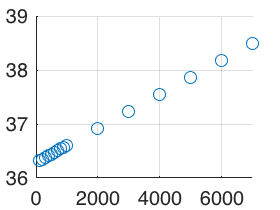

s1 = scatter (h, SFC);
grid on;

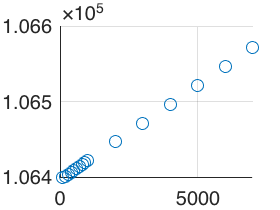


s2 = scatter (h, Fn);
grid on;

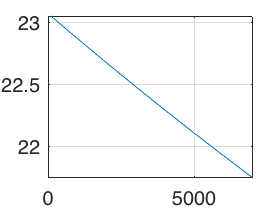


s3 = plot (h, ETATH);
grid on;